MA525 Homework 2

Aaron Cornelius

2020-10-11

## Problem 1

Consider data $\omega_n$ where $n=1,\ldotp \ldotp \ldotp ,N$ indexes individual measurements. Each $\omega_n$ is obtained through a $\mathrm{Normal}\left(\mu ,v\right)$ distribution. Assume the variance $v$ has a known value. On $\mu$ use a $\mathrm{Normal}\left(M,V\right)$ prior where $M,V$ have known values.

### (i)

In statistical notation, this problem can be written as:


$$\begin{array}{l}
\mu ~\mathrm{Normal}\left(M,V\right)\\
\omega_n |\mu ~\mathrm{Normal}\left(\mu ,v\right)
\end{array}$$


### (ii)


$$p\left(\mu \right)=\mathrm{Normal}\left(\mu ;M,V\right)=\frac{1}{\sqrt{2\pi v}}\mathrm{exp}\left(-\frac{1}{2v}{\left(x-\mu \right)}^2 \right)$$


The PDF of the normal distribution, written using the variance, is:


$$p\left(x\right)=\frac{1}{\sqrt{2\pi v}}\mathrm{exp}\left(-\frac{1}{2v}{\left(x-\mu \right)}^2 \right)$$


Therefore, there are two probability functions. The first explicitly defines the probability density of the distribution of $\mu$:


$$p_{\mu } \left(\mu \right)=\frac{1}{\sqrt{2\pi V}}\mathrm{exp}\left(-\frac{1}{2V}{\left(\mu -M\right)}^2 \right)$$


The second defines the probability of an observed value $\omega$ conditioned on $\mu$:


$$p_{\omega } \left(\omega |\mu \right)=\frac{1}{\sqrt{2\pi v}}\mathrm{exp}\left(-\frac{1}{2v}{\left(\omega -\mu \right)}^2 \right)$$


The likelihood is taken by, the likelihood function for some set of observations $\omega_n$ is:


$$\begin{array}{l}
p\left(\omega_{1:N} |\mu ;\right)=\prod_{n=1}^N p\left(\omega_n |\mu \right)\\
=\prod_{n=1}^N \left(\frac{1}{\sqrt{2\pi v}}\mathrm{exp}\left(-\frac{1}{2v}{\left(\omega_n -\mu \right)}^2 \right)\right)\\
=\prod_{n=1}^N \left(\frac{1}{\sqrt{2\pi v}}\right)\prod_{n=1}^N \left(\mathrm{exp}\left(-\frac{1}{2v}{\left(\omega_n -\mu \right)}^2 \right)\right)\\
={\left(\frac{1}{\sqrt{2\pi v}}\right)}^N \mathrm{exp}\left(-\frac{1}{2v}\sum_{n=1}^N {\left(\omega_n -\mu \right)}^2 \right)
\end{array}$$


The posterior can be calculated by multiplying the likelihood by the prior distribution:


$$\begin{array}{l}
p\left(\mu |\omega_{1:N} \right)\propto p\left(\omega_{1:N} |\mu \right)p\left(\mu \right)\\
=\left({\left(\frac{1}{\sqrt{2\pi v}}\right)}^N \mathrm{exp}\left(-\frac{1}{2v}\sum_{n=1}^N {\left(\omega_n -\mu \right)}^2 \right)\right)\left(\frac{1}{\sqrt{2\pi V}}\mathrm{exp}\left(-\frac{1}{2V}{\left(\mu -M\right)}^2 \right)\right)\\
\propto \mathrm{exp}\left(-\frac{1}{2v}\sum_{n=1}^N {\left(\omega_n -\mu \right)}^2 \right)\mathrm{exp}\left(-\frac{1}{2V}{\left(\mu -M\right)}^2 \right)\\
=\mathrm{exp}\left(-\frac{1}{2v}\sum_{n=1}^N {\left(\omega_n -\mu \right)}^2 -\frac{1}{2V}{\left(M-\mu \right)}^2 \right)=\mathrm{exp}\left(-\frac{1}{2}\left(\frac{1}{v}\sum_{n=1}^N {\left(\omega_n -\mu \right)}^2 +\frac{1}{V}{\left(M-\mu \right)}^2 \right)\right)
\end{array}$$
 

To simplify the equation, define $f=\frac{1}{v}\sum_{n=1}^N {\left(\omega_n -\mu \right)}^2 +\frac{1}{V}{\left(M-\mu \right)}^2$. Therefore, by defining $\omega^‾ =\frac{1}{N}\sum_{n=1}^N \omega_n$:


$$\begin{array}{l}
p\left(\mu \left|\omega_{1:N} \right.\right)\propto \mathrm{exp}\left(-\frac{1}{2}f\right)\\
f=\frac{1}{v}\sum_{n=1}^N {\left(\omega_n -\mu \right)}^2 +\frac{1}{V}{\left(M-\mu \right)}^2 \\
=\frac{1}{v}\sum_{n=1}^N {\left(\left(\omega_n -\omega^‾ \right)+\left(\omega^‾ -\mu \right)\right)}^2 +\frac{1}{V}{\left(M-\mu \right)}^2 \\
=\frac{1}{v}\left(\sum_{n=1}^N {\left(\omega_n -\omega^‾ \right)}^2 +2\sum_{n=1}^N \left(\omega_n -\omega^‾ \right)\left(\omega^‾ -\mu \right)+\sum_{n=1}^N {\left(\omega^‾ -\mu \right)}^2 \right)+\frac{1}{V}{\left(M-\mu \right)}^2 \\
=\frac{1}{v}\left(\sum_{n=1}^N {\left(\omega_n -\omega^‾ \right)}^2 +2\left(\omega^‾ -\mu \right)\sum_{n=1}^N \left(\omega_n -\omega^‾ \right)+N{\left(\omega^‾ -\mu \right)}^2 \right)+\frac{1}{V}{\left(M-\mu \right)}^2 
\end{array}$$


Since $\sum_{n=1}^N \left(\omega_n -\omega^‾ \right)=0$, this further simplifies to:


$$\begin{array}{l}
f=\frac{1}{v}\left(\sum_{n=1}^N {\left(\omega_n -\omega^‾ \right)}^2 +N{\left(\omega^‾ -\mu \right)}^2 \right)+\frac{1}{V}{\left(M-\mu \right)}^2 \\
=\frac{1}{v}\sum_{n=1}^N {\left(\omega_n -\omega^‾ \right)}^2 +\frac{1}{v}N{\left(\omega^‾ -\mu \right)}^2 +\frac{1}{V}{\left(M-\mu \right)}^2 
\end{array}$$


Substituting back into the original equation:


$$\begin{array}{l}
p\left(\mu \left|\omega_{1:N} \right.\right)\propto \mathrm{exp}\left(-\frac{1}{2}\left(\frac{1}{v}\sum_{n=1}^N {\left(\omega_n -\omega^‾ \right)}^2 +\frac{1}{v}N{\left(\omega^‾ -\mu \right)}^2 +\frac{1}{V}{\left(M-\mu \right)}^2 \right)\right)\\
=\mathrm{exp}\left(-\frac{1}{2v}\sum_{n=1}^N {\left(\omega_n -\omega^‾ \right)}^2 \right)\mathrm{exp}\left(-\frac{1}{2}\left(\frac{1}{v}N{\left(\omega^‾ -\mu \right)}^2 +\frac{1}{V}{\left(M-\mu \right)}^2 \right)\right)\\
\propto \mathrm{exp}\left(-\frac{1}{2}\left(\frac{1}{v}N{\left(\omega^‾ -\mu \right)}^2 +\frac{1}{V}{\left(M-\mu \right)}^2 \right)\right)
\end{array}$$


Now define a quadratic polynomial:


$$\begin{array}{l}
g=\frac{N}{v}{\left(\omega^‾ -\mu \right)}^2 +\frac{1}{V}{\left(M-\mu \right)}^2 \\
=\frac{N}{v}\mu^2 -\frac{2N\omega^‾ \mu }{v}+\frac{N{\omega^‾ }^2 }{v}+\frac{M^2 }{V}-\frac{2M\mu }{V}+\frac{\mu^2 }{V}\\
=\left(\frac{N}{v}+\frac{1}{V}\right)\left(\mu^2 -\frac{2\mu }{\frac{N}{v}+\frac{1}{V}}\left(\frac{N\omega^‾ }{v}+\frac{M}{V}\right)+\frac{1}{\frac{N}{v}+\frac{1}{V}}\left(\frac{N{\omega^‾ }^2 }{v}+\frac{M^2 }{V}\right)\right)
\end{array}$$


Now some proportionality constant $K$ can be multiplied in, allowing the formula to be written:


$$g=\left(\frac{N}{v}+\frac{1}{V}\right){\left(\mu -\frac{\left(\frac{N\omega^‾ }{v}+\frac{M}{V}\right)}{\frac{N}{v}+\frac{1}{V}}\right)}^2 +K$$


In the original equation, this equals:


$$\begin{array}{l}
p\left(\mu \left|\omega_{1:N} \right.\right)\propto \mathrm{exp}\left(-\frac{1}{2}g\right)=\mathrm{exp}\left(-\frac{1}{2}K\right)\mathrm{exp}\left(-\frac{1}{2}\left(\frac{1}{{\left(\frac{N}{v}+\frac{1}{V}\right)}^{-1} }\right)\left({\left(\mu -\frac{\left(\frac{N\omega^‾ }{v}+\frac{M}{V}\right)}{\frac{N}{v}+\frac{1}{V}}\right)}^2 \right)\right)\\
\propto \mathrm{exp}\left(-\frac{1}{2}\left(\frac{1}{{\left(\frac{N}{v}+\frac{1}{V}\right)}^{-1} }\right)\left({\left(\mu -\frac{\left(\frac{N\omega^‾ }{v}+\frac{M}{V}\right)}{\frac{N}{v}+\frac{1}{V}}\right)}^2 \right)\right)
\end{array}$$


This matches the form of the normal distribution $\mathrm{Normal}\left(\mu^* ,v^* \right)$ where:


$$v^* =\frac{1}{\left(\frac{N}{v}+\frac{1}{V}\right)},\mu^* =v^* \left(\frac{N\omega^‾ }{v}+\frac{M}{V}\right)$$


These can also be simplified:


$$\begin{array}{l}
v^* =\frac{1}{\left(\frac{N}{v}+\frac{1}{V}\right)}=\frac{1}{\frac{V}{V}\frac{N}{v}+\frac{v}{v}\frac{1}{V}}=\frac{1}{\frac{\mathrm{VN}+v}{\mathrm{Vv}}}=\frac{\mathrm{Vv}}{\mathrm{VN}+v}\\
\mu^* =\frac{\mathrm{Vv}}{\mathrm{VN}+v}\left(\frac{N\omega^‾ }{v}+\frac{M}{V}\right)=\frac{\mathrm{Vv}}{\mathrm{VN}+v}\left(\frac{V}{V}\frac{N\omega^‾ }{v}+\frac{v}{v}\frac{M}{V}\right)\\
=\frac{\mathrm{Vv}}{\mathrm{VN}+v}\left(\frac{\mathrm{VN}\omega^‾ +\mathrm{vM}}{\mathrm{Vv}}\right)\\
=\frac{\mathrm{VN}\omega^‾ +\mathrm{vM}}{\mathrm{VN}+v}
\end{array}$$


The equation can thus be written:


$$\begin{array}{l}
p\left(\mu |\omega_{1:N} \right)\propto \mathrm{exp}\left(-\frac{1}{2v^* }{\left(\mu -\mu^* \right)}^2 \right)\\
\Rightarrow p\left(\mu |\omega_{1:N} \right)=C\cdot \mathrm{exp}\left(-\frac{1}{2v^* }{\left(\mu -\mu^* \right)}^2 \right)=p\left(\mathrm{Normal}\left(\mu^* ,v^* \right)\right)=p_{\mu } \left(\mu \right)=\frac{1}{\sqrt{2\pi v^* }}\mathrm{exp}\left(-\frac{1}{2v^* }{\left(\mu -\mu^* \right)}^2 \right)\\
\Rightarrow C=\frac{1}{\sqrt{2\pi v^* }}
\end{array}$$


Therefore:

$p\left(\mu \left|\omega_{1:N} \right.\right)=\frac{1}{\sqrt{2\pi v^* }}\cdot \mathrm{exp}\left(-\frac{1}{2v^* }{\left(\mu -\mu^* \right)}^2 \right)$, where $v^* =\frac{\mathrm{Vv}}{\mathrm{VN}+v},\mu^* =\frac{\mathrm{VN}\omega^‾ +\mathrm{vM}}{\mathrm{VN}+v}$

### (iii)

This graph compares the prior and posterior results for the distribution of $\mu$. The prior distribution was very wide, indicating great uncertainty about what the true mean was. After the sample points are added, the posterior has converged much more strongly towards a single value.

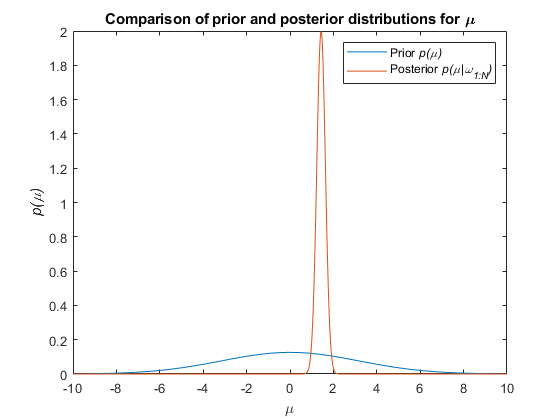

v=1;
M=0;
V=10;

load normal_normal;
vStar = V*v/(V*length(w)+v);
muStar = (V*length(w)*mean(w)+v*M)/(V*length(w)+v);

prior = @(mu)1./(sqrt(2*pi*V)).*exp(-1/(2*V).*(mu-M).^2);
posterior =  @(mu)1./(sqrt(2*pi*vStar)).*exp(-1/(2*vStar).*(mu-muStar).^2);

figure
clf
fplot(prior, [-10 10])
hold on
fplot(posterior, [-10 10])
xlabel('\mu')
ylabel('\it{p(\mu)}')
legend(["Prior \it{p(\mu)}" "Posterior \it{p(\mu|\omega_{1:N})}"])
title('Comparison of prior and posterior distributions for \mu')

### (iv)

The probability that $\mu <0$ can be found by integrating the prior and posterior probabilties from negative infinity to infinity. Since it is not possible to numerically integrate negative infinity, the integrals will instead be performed from -100 to 0. From visual inspection of the graph of the prior and posteriors, it can be see that the probability past -10 is extremely low, and thus there will be little effect on the overall integration.


$$\begin{array}{l}
p\left(\mu \right)<0\ldotp 5\approx \int_{-100}^0 p\left(\mu \right)\;d\mu =0\ldotp 5=50%\\
p\left(\mu |\omega_{1:N} \right)<0\ldotp 5\approx \int_{-100}^0 p\left(\mu |\omega_{1:N} \right)\;d\mu \approx 3\ldotp 44\cdot {10}^{-13} =3\ldotp 44\cdot {10}^{-11} %
\end{array}$$


These results make intuitive sense: the prior has a mean of 0, so there is a 50% chance that the value will be less than the mean (i.e., negative.) The posterior is centered roughly around $\mu =1$, with very little probability that $\mu <0$.

integral(prior, -100, 0);
integral(posterior, -100, 0);

### (v)

The maximum a posteriori estimate for $\mu$ can be found by differentiating the probability distribution and finding the point where the slope is equal to zero.

$p\left(\mu \left|\omega_{1:N} \right.\right)=\frac{1}{\sqrt{2\pi v^* }}\cdot \mathrm{exp}\left(-\frac{1}{2v^* }{\left(\mu -\mu^* \right)}^2 \right)$, where $v^* =\frac{\mathrm{Vv}}{\mathrm{VN}+v},\mu^* =\frac{\mathrm{VN}\omega^‾ +\mathrm{vM}}{\mathrm{VN}+v}$

$\frac{d}{d\mu }p\left(\mu \left|\omega_{1:N} \right.\right)=\frac{1}{\sqrt{2\pi v^* }}\cdot \left(f^{\prime } \left(g\left(\mu \right)\right)\cdot g^{\prime } \left(\mu \right)\right)$, where $f\left(\mu \right)=\mathrm{exp}\left(\mu \right),g\left(\mu \right)=-\frac{1}{2v^* }{\left(\mu -\mu^* \right)}^2$


$$\begin{array}{l}
=\frac{1}{\sqrt{2\pi v^* }}\cdot \mathrm{exp}\left(-\frac{1}{2v^* }{\left(\mu -\mu^* \right)}^2 \right)\cdot \left(-\frac{1}{v^* }\left(\mu -\mu^* \right)\right)\\
0=\frac{1}{\sqrt{2\pi v^* }}\cdot \mathrm{exp}\left(-\frac{1}{2v^* }{\left(\mu -\mu^* \right)}^2 \right)\cdot \left(-\frac{1}{v^* }\left(\mu -\mu^* \right)\right)=\mathrm{exp}\left(-\frac{1}{2v^* }{\left(\mu -\mu^* \right)}^2 \right)\cdot \left(-\frac{1}{v^* }\left(\mu -\mu^* \right)\right)
\end{array}$$


This is true when either $\mathrm{exp}\left(-\frac{1}{2v^* }{\left(\mu -\mu^* \right)}^2 \right)=0$ or $\left(-\frac{1}{v^* }\left(\mu -\mu^* \right)\right)=0$. However, the exponential function can never be equal to zero. Therefore:


$$\begin{array}{l}
\left(-\frac{1}{v^* }\left(\mu -\mu^* \right)\right)=0=\left(\mu -\mu^* \right)\\
\Rightarrow \mu =\mu^* =\frac{\mathrm{VN}\omega^‾ +\mathrm{vM}}{\mathrm{VN}+v}\approx 1\ldotp 4335
\end{array}$$


This result makes intuitive sense: the peak of a normal distribution is always at its mean value.

### (vi)

Each measurement $\omega_n$ is in units of $\left\lbrack \mathrm{au}\right\rbrack$. In the $\mathrm{Normal}\left(\mu ,v\right)$ distribution that the measurements are drawn from, each measurement is subtracted from the mean value $\mu$. Therefore, they must have the same units, so the units of $\mu$ must also be $\left\lbrack \mathrm{au}\right\rbrack$. Similarly, in the prior distribution $\mathrm{Normal}\left(M,V\right)$, each value of $\mu$ is subtracted from the prior mean $M$, so the units of $M$ must also be $\left\lbrack \mathrm{au}\right\rbrack$. In both cases, the differences between the mean values $\mu ,M$ and the observed values $\omega_n ,\mu$ are then squared (giving units of $\left\lbrack {\mathrm{au}}^2 \right\rbrack$), and divided by the relevant variances $v,V$. The result of that division must be unitless for the exponential. Therefore, $v,V$ must have the same units as $\omega_n^2 ,\mu^2$: $\left\lbrack {\mathrm{au}}^2 \right\rbrack$.

In summary:


$$\begin{array}{l}
\mu :\left\lbrack \mathrm{au}\right\rbrack \\
M:\left\lbrack \mathrm{au}\right\rbrack \\
v:\left\lbrack {\mathrm{au}}^2 \right\rbrack \\
V:\left\lbrack {\mathrm{au}}^2 \right\rbrack 
\end{array}$$


## Problem 2

Set up a Bayesian model for discrete measurements. Consider data $\omega_n$, where each value $n=1,\ldotp \ldotp \ldotp ,N$ is an individual measurement. $\omega_n$ is drawn from a $\mathrm{Geometric}\left(\pi \right)$ distribution with probability mass given by:


$$p\left(\omega \right)=\left\lbrace \begin{array}{ll}
{\left(1-\pi \right)}^{\omega } \pi  & \omega \ge 0\\
0 & \mathrm{else}
\end{array}\right.$$


The prior of $\pi$ is defined with a $\mathrm{Beta}\left(\alpha ,\beta \right)$ distribution where $\alpha ,\beta$ have known values. The probability density of the Beta distribution is:


$$p\left(\pi \right)=\left\lbrace \begin{array}{ll}
\frac{{\pi^{\alpha -1} \left(1-\pi \right)}^{\beta -1} }{B\left(\alpha ,\beta \right)} & 0\le \pi \le 1\\
\mathrm{else} & 0
\end{array}\right.$$


where $B\left(\alpha ,\beta \right)$ is the $\mathrm{Beta}$ function:


$$B\left(x,y\right)=\int_0^1 t^{x-1} {\left(1-t\right)}^{y-1} \;dt$$


### (i)

In statistical notation, this problem can be written as:


$$\begin{array}{l}
\pi ~\mathrm{Beta}\left(\alpha ,\beta \right)\\
\omega_n |\pi ~\mathrm{Geometric}\left(\pi \right)
\end{array}$$



$$p\left(\omega \left|\pi \right.\right)={\left(1-\pi \right)}^{\omega } \;\pi$$



$$p\left(\pi \right)=\frac{\pi^{\alpha -1} {\left(1-\pi \right)}^{\beta -1} }{B\left(\alpha ,\beta \right)}$$


### (ii)

The posterior can be calculated as $p\left(\pi |\omega_{1:N} \right)=C\;p\left(\omega_{1:N} |\pi \right)\;p\left(\pi \right)$. $p\left(\pi \right)$ is defined from the posterior. The next step is to calculate $p\left(\omega_{1:N} |\pi \right)$, which can be done by taking the product of the probability of each individual observation conditioned on $\pi$:


$$p\left(\omega_{1:N} |\pi \right)=\prod_{n=1}^N p\left(\omega_n |\pi \right)=\prod_{n=1}^N \left({\left(1-\pi \right)}^{\omega_n } \pi \right)=\pi^N {\left(1-\pi \right)}^{\sum_{n=1}^N \omega_n }$$


Therefore, the posterior can be written:


$$\begin{array}{l}
p\left(\pi |\omega_{1:N} \right)\propto p\left(\omega_{1:N} |\pi \right)\;p\left(\pi \right)=\pi^N {\left(1-\pi \right)}^{\sum_{n=1}^N \omega_n } \frac{\pi^{\alpha -1} {\left(1-\pi \right)}^{\beta -1} }{B\left(\alpha ,\beta \right)}\\
\propto {\left(1-\pi \right)}^{\sum_{n=1}^N \omega_n } \pi^{\alpha -1} {\left(1-\pi \right)}^{\beta -1} =\pi^{N+\alpha -1} {\left(1-\pi \right)}^{\beta -1+\sum_{n=1}^N \omega_n } 
\end{array}$$


It is known that $\int_0^1 p\left(\pi |\omega_{1:N} \right)=1$. The next step is to find the normalization coefficient $C$. This is simple for this equation: the posterior $p\left(\pi |\omega_{1:N} \right)$ is proportional to a beta distribution with updated parameters $\alpha^* ,\beta^*$ where:

$\alpha^* =\alpha +N,\beta^* =\beta +\sum_{n=1}^N \omega_n$. Therefore:


$$\begin{array}{l}
p\left(\pi |\omega_{1:N} \right)=C\pi^{\alpha^* -1} {\left(1-\pi \right)}^{\beta^* -1} \\
\Rightarrow 1=\int_0^1 C\pi^{\alpha -1} {\left(1-\pi \right)}^{\beta -1+\sum_{n=1}^N \omega_n } \;d\pi =\int_0^1 \frac{\pi^{\alpha^* -1} {\left(1-\pi \right)}^{\beta^* -1} }{B\left(\alpha^* ,\beta^* \right)}\;d\pi \\
=\frac{1}{B\left(\alpha^* ,\beta^* \right)}\int_0^1 \pi^{\alpha^* -1} {\left(1-\pi \right)}^{\beta^* -1} \;d\pi \\
\Rightarrow C=\frac{1}{B\left(\alpha^* ,\beta^* \right)}=\frac{1}{B\left(\alpha +N,\beta +\sum_{n=1}^N \omega_n \right)}\\
\Rightarrow p\left(\pi |\omega_{1:N} \right)=\frac{\pi^{\alpha +N-1} {\left(1-\pi \right)}^{\beta +\sum_{n=1}^N \omega_n -1} }{B\left(\alpha +N,\beta +\sum_{n=1}^N \omega_n \right)}
\end{array}$$


### (iii)

The following graph compares the prior and posterior distributions of $\pi$ when $\alpha =\beta =1$ and updating using the provided observations $\omega_{1:N}$. It can be seen that the prior distribution is entirely uniform over $0\le \pi \le 1$. This makes sense since for the case $\alpha =\beta =1$, the prior distribution PDF simplifies to $p\left(\pi \right)=\frac{\pi^0 {\left(1-\pi \right)}^0 }{B\left(1,1\right)}=\frac{1}{B\left(1,1\right)}$ when $0\le \pi \le 1$.

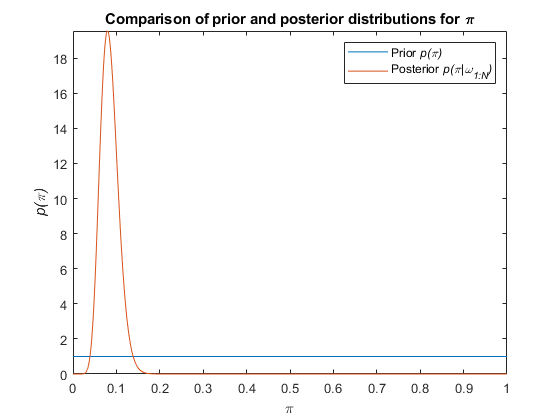

load geo_beta.mat
prior = @(x) (x.^(1-1).*(1-x).^(1-1))./beta(1,1);
posterior = @(x) (x.^(1+length(w)-1).*(1-x).^(1+sum(w)-1))./(beta(1+length(w), 1+sum(w)));
figure
clf
fplot(prior, [0 1])
hold on
fplot(posterior, [0 1])
xlabel('\pi')
ylabel('\it{p(\pi)}')
legend(["Prior \it{p(\pi)}" "Posterior \it{p(\pi|\omega_{1:N})}"])
title('Comparison of prior and posterior distributions for \pi')

### (iv)

The probability that $\pi >0\ldotp 15$ can be determined by integrating the prior and posterior distributions from 0.15 to 1. This is done numerically. Therefore:


$$\begin{array}{l}
p\left(\pi \right)>0\ldotp 15=\int_{0\ldotp 15}^1 \frac{\pi^{\alpha -1} {\left(1-\pi \right)}^{\beta -1} }{B\left(\alpha ,\beta \right)}\;d\pi =0\ldotp 85=85%\\
p\left(\pi |\omega_{1:N} \right)>0\ldotp 15=\int_{0\ldotp 15}^1 \frac{\pi^{\alpha -1} {\left(1-\pi \right)}^{\beta -1} }{B\left(\alpha ,\beta \right)}\;d\pi \approx 0\ldotp 0034\approx 0\ldotp 34%
\end{array}$$


This matches up with visual inspection from the graph above: the posterior is uniform and thus the probability will be proportional to the percentage of the range integrated over (i.e., $100%-15%=85%$), but the posterior is extremely confident that the value of $\pi$ will be just below 0.1, with very little probability where $\pi >0\ldotp 15$.

integral(prior, 0.15, 1);
integral(posterior, 0.15, 1);

### (v)

The maximum value of the posterior can be analytically determined by differentiating the posterior probability distribution $p\left(\pi \left|\omega_{1:N} \right.\right)$ and finding the zero-slope point:


$$\begin{array}{l}
\frac{d}{d\pi }p\left(\pi |\omega_{1:N} \right)=\frac{1}{B\left(\alpha^* ,\beta^* \right)}\left(\left(\frac{d}{d\pi }\pi^{\alpha +N-1} \right){\left(1-\pi \right)}^{\beta +\sum_{n=1}^N \omega_n -1} +\left(\frac{d}{d\pi }{\left(1-\pi \right)}^{\beta +\sum_{n=1}^N \omega_n -1} \right)\pi^{\alpha +N-1} \right)\\
=\frac{1}{B\left(\alpha^* ,\beta^* \right)}\left({\;\left(\alpha +N-1\right)\pi^{a+N-2} \left(1-\pi \right)}^{\beta +\sum_{n=1}^N \omega_n -1} +\left(-\beta +\sum_{n=1}^N \omega_n -1\right){\left(1-\pi \right)}^{\beta +\sum_{n=1}^N \omega_n -1} \pi^{\alpha +N-1} \right)\\
0=\frac{1}{B\left(\alpha^* ,\beta^* \right)}\left({\;\left(\alpha +N-1\right)\pi^{a+N-2} \left(1-\pi \right)}^{\beta +\sum_{n=1}^N \omega_n -1} +\left(-\beta +\sum_{n=1}^N \omega_n -1\right){\left(1-\pi \right)}^{\beta +\sum_{n=1}^N \omega_n -1} \pi^{\alpha +N-1} \right)\\
=\left({\;\left(\alpha +N-1\right)\pi^{a+N-2} \left(1-\pi \right)}^{\beta +\sum_{n=1}^N \omega_n -1} +\left(-\beta +\sum_{n=1}^N \omega_n -1\right){\left(1-\pi \right)}^{\beta +\sum_{n=1}^N \omega_n -2} \pi^{\alpha +N-1} \right)\\
\Rightarrow {\;\left(\alpha +N-1\right)\pi^{a+N-2} \left(1-\pi \right)}^{\beta +\sum_{n=1}^N \omega_n -1} =\left(\beta +\sum_{n=1}^N \omega_n -1\right){\left(1-\pi \right)}^{\beta +\sum_{n=1}^N \omega_n -2} \pi^{\alpha +N-1} \\
\Rightarrow \left(\alpha +N-1\right)\left(1-\pi \right)=\left(\beta +\sum_{n=1}^N \omega_n -1\right)\pi \\
\Rightarrow \frac{\left(1-\pi \right)}{\pi }=\frac{\left(\beta +\sum_{n=1}^N \omega_n -1\right)}{\left(a+N-1\right)}=\frac{1}{\pi }-1\\
\sum_{n=1}^N \omega_n =162,N=14,\alpha =1,\beta =1\\
\Rightarrow \frac{1}{\pi }-1=\frac{\left(1+162-1\right)}{\left(1+14-1\right)}=\frac{162}{14}\\
\Rightarrow \frac{1}{\pi }=\frac{176}{14}\\
\Rightarrow \pi =\frac{14}{176}~0\ldotp 0795
\end{array}$$


This matches up with visual inspection of the graph above: the peak is slightly below $\pi =0\ldotp 1$. This can also be verified by evaluating $p\left(\pi \left|\omega_{1:N} \right.\right)$ at points slightly above and below $\frac{14}{176}$ and making sure that both points are lower than $p\left(\frac{14}{176}\left|\omega_{1:N} \right.\right)$:


$$\begin{array}{l}
p\left(\frac{13}{176}\left|\omega_{1:N} \right.\right)\approx 17\ldotp 7754\\
p\left(\frac{14}{176}\left|\omega_{1:N} \right.\right)\approx 19\ldotp 5531\\
p\left(\frac{15}{176}\left|\omega_{1:N} \right.\right)\approx 18\ldotp 8391
\end{array}$$


posterior(13/176);
posterior(14/176);
posterior(15/176);

## Problem 3

Determine if the models in the previous problems belong to the exponential family. For this to be true, with $x$ as the parameters and $y$ as the measurements, the function must be able to be written as:


$$\begin{array}{l}
p\left(x\right)\propto {\left(G\left(x\right)\right)}^{\eta } \;\mathrm{exp}\left(\phi \left(x\right)\nu \right)\\
p\left(y|x\right)=F\left(y\right)G\left(x\right)\;\mathrm{exp}\left(\phi \left(x\right)U\left(y\right)\right)
\end{array}$$


### (i)

For the conjugate model to belong to the exponential family, the following must be true:


$$\begin{array}{l}
p\left(\mu \right)\propto {G\left(\mu \right)}^{\eta } \;\mathrm{exp}\left(\phi \left(\mu \right)\;\nu \right)\\
p\left(\omega |\mu \right)=F\left(\omega \right)G\left(\mu \right)\;\mathrm{exp}\left(\phi \left(\mu \right)U\left(\omega \right)\right)
\end{array}$$


Start by looking at the probability of $\omega$ conditioned on $\mu$ first:


$$\begin{array}{l}
p\left(\omega \left|\mu \right.\right)=\left(\frac{1}{\sqrt{2\pi v}}\right)\mathrm{exp}\left(-\frac{1}{2v}{\left(\omega -\mu \right)}^2 \right)\\
=\left(\frac{1}{\sqrt{2\pi v}}\right)\mathrm{exp}\left(-\frac{1}{2v}\left(\omega^2 -2\omega \mu \right)+\mu^2 \right)\\
=\left(\frac{1}{\sqrt{2\pi v}}\right)\mathrm{exp}\left(-\frac{\omega^2 }{2v}\right)\mathrm{exp}\left(\frac{\omega \mu }{v}-\frac{\mu^2 }{2v}\right)
\end{array}$$


Define $F\left(\omega \right)=\mathrm{exp}\left(-\frac{\omega^2 }{2v}\right)$. Therefore:


$$p\left(\omega \left|\mu \right.\right)=F\left(\omega \right)\;\left(\frac{1}{\sqrt{2\pi v}}\right)\mathrm{exp}\left(\omega \frac{\mu }{v}-\frac{\mu^2 }{2v}\right)$$


Define $G\left(\mu \right)=\left(\frac{1}{\sqrt{2\pi v}}\right)\mathrm{exp}\left(-\frac{\mu^2 }{2v}\right)$. Therefore:


$$p\left(\omega |\mu \right)=F\left(\omega \right)G\left(\mu \right)\mathrm{exp}\left(\frac{\omega \mu }{v}\right)$$


Define $\phi \left(\mu \right)=\frac{\mu }{v},U\left(\omega \right)=\omega$:


$$p\left(\omega \left|\mu \right.\right)=F\left(\omega \right)G\left(\mu \right)\mathrm{exp}\left(\phi \left(\mu \right)U\left(\omega \right)\right)$$


Now, the prior $p\left(\mu \right)$ must be defined using this same set of equations:


$$\begin{array}{l}
p\left(\mu \right)=\frac{1}{\sqrt{2\pi V}}\mathrm{exp}\left(-\frac{1}{2V}{\left(\mu -M\right)}^2 \right)\propto {G\left(\mu \right)}^{\eta } \;\mathrm{exp}\left(\phi \left(\mu \right)\;\nu \right)\\
={\left(\left(\frac{1}{\sqrt{2\pi v}}\right)\mathrm{exp}\left(-\frac{\mu^2 }{2v}\right)\right)}^{\eta } \;\mathrm{exp}\left(\nu \;\mu \right)\\
={\left(\frac{1}{\sqrt{2\pi v}}\right)}^{\eta } \mathrm{exp}\left(\nu \;\mu -\eta \frac{\mu^2 }{2v}\right)
\end{array}$$


If $\eta =\frac{v}{V}$ and $\nu =\frac{M}{V}$:


$$\begin{array}{l}
p\left(\mu \right)\propto {\left(\frac{1}{\sqrt{2\pi v}}\right)}^{\frac{v}{V}} \mathrm{exp}\left(\frac{M}{V}\mu -\frac{v}{V}\frac{\mu^2 }{2v}\right)\\
\propto \mathrm{exp}\left(\frac{M\mu }{V}-\frac{\mu^2 }{2V}\right)\\
\propto \mathrm{exp}\left(\frac{M\mu }{V}-\frac{\mu^2 }{2V}\right)\mathrm{exp}\left(-\frac{1}{2}\frac{M^2 }{V}\right)\\
=\mathrm{exp}\left(\frac{M\mu }{V}-\frac{\mu^2 }{2V}-\frac{M^2 }{2V}\right)\\
=\mathrm{exp}\left(-\frac{1}{2V}\left(\mu^2 -M\mu +M^2 \right)\right)\\
=\mathrm{exp}\left(-\frac{1}{2V}{\left(M-\mu \right)}^2 \right)
\end{array}$$


This is the correct form for the prior, with $p\left(\mu \right)=C\cdot \mathrm{exp}\left(-\frac{1}{2V}{\left(M-\mu \right)}^2 \right)$. Therefore, the normal conjugate model from problem 1 is part of the exponential family. While this examination only looked at the case where there was a single observation (i.e., $N=1$), this scales to any number of examples, since the posterior resulting from updating with all samples simultaneously is equal to the posterior obtained by chaining the samples by applying a sample, taking the posterior, and treating it as the prior for the next sample, throughout all the samples.

### (ii)

For the conjugate model to belong to the exponential family, the following must be true:


$$\begin{array}{l}
p\left(\pi \right)\propto {G\left(\pi \right)}^{\eta } \;\mathrm{exp}\left(\phi \left(\pi \right)\;\nu \right)\\
p\left(\omega \left|\pi \right.\right)=F\left(\omega \right)G\left(\pi \right)\;\mathrm{exp}\left(\phi \left(\pi \right)U\left(\omega \right)\right)
\end{array}$$


The prior is:

$p\left(\pi \right)=\frac{\pi^{\alpha -1} {\left(1-\pi \right)}^{\beta -1} }{B\left(\alpha ,\beta \right)}\propto \pi^{\alpha -1} {\left(1-\pi \right)}^{\beta -1}$, and the likelihood of observing some sample given $\mu$ is:


$$p\left(\omega |\pi \right)=\left\lbrace \begin{array}{ll}
{\left(1-\pi \right)}^{\omega } \pi  & \omega \ge 0\\
0 & \mathrm{else}
\end{array}\right.$$


First, the probability of $\omega$ conditioned on $\pi$ for $0\le \pi$will be examined:


$$\begin{array}{l}
p\left(\omega |\pi \right){=\left(1-\pi \right)}^{\omega } \pi \\
=\pi \mathrm{exp}\left(\mathrm{ln}\left(1-\pi \right)\omega \right)
\end{array}$$


Let $G\left(\pi \right)=\pi ,\phi \left(\pi \right)=\mathrm{ln}\left(1-\pi \right),F\left(\omega \right)=1,U\left(\omega \right)=\omega$:


$$p\left(\omega |\pi \right)=G\left(\pi \right)\;\mathrm{exp}\left(\phi \left(\pi \right)U\left(\omega \right)\right)$$


Now the prior $p\left(\pi \right)$ must be constructed using these equations:


$$p\left(\pi \right)=\pi^{\alpha -1} {\left(1-\pi \right)}^{\beta -1} \propto {G\left(\pi \right)}^{\eta } \;\mathrm{exp}\left(\phi \left(\pi \right)\;\nu \right)=\pi^{\eta } \;\mathrm{exp}\left(\mathrm{ln}\left(1-\pi \right)\;\nu \right)$$


Assume $\eta =\alpha -1$:


$$\begin{array}{l}
p\left(\pi \right)\propto \pi^{\alpha -1} \;\mathrm{exp}\left(\mathrm{ln}\left(1-\pi \right)\;\nu \right)\\
=\pi^{\alpha -1} {\left(1-\pi \right)}^{\nu } 
\end{array}$$


Assume $\nu =\beta -1$:


$$p\left(\pi \right)\propto \pi^{\alpha -1} {\left(1-\pi \right)}^{\beta -1}$$


This is of the correct form for the input beta distribution, with $p\left(\pi \right)=C\cdot \pi^{\alpha -1} {\left(1-\pi \right)}^{\beta -1}$. Therefore the beta conjugate model from problem 1 is part of the exponential family. As before, while only a single sample was examined for the likelihood function, this is equivilent to evaluating the likelihood for an arbitrary number of samples.